# `Activity 7`

## `Sub-Space Filtering`

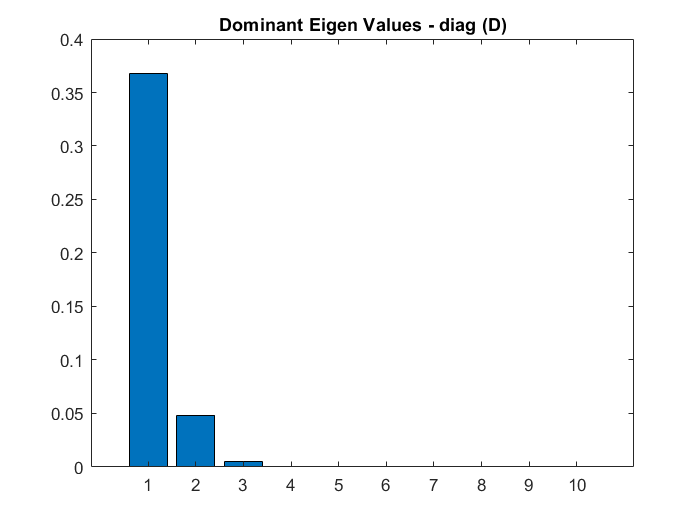

[data, Fs] = audioread('sarigamapa.wav');
Time = audioinfo ('sarigamapa.wav').Duration;

N = 10;

signal = data (:,1);
XX = buffer (signal,N,N-1);
X = XX(:,10: end);

S = cov (X');
[V,D] = eigs (S,10);

figure (01); 
bar (diag (D))
title('Dominant Eigen Values - diag (D)')

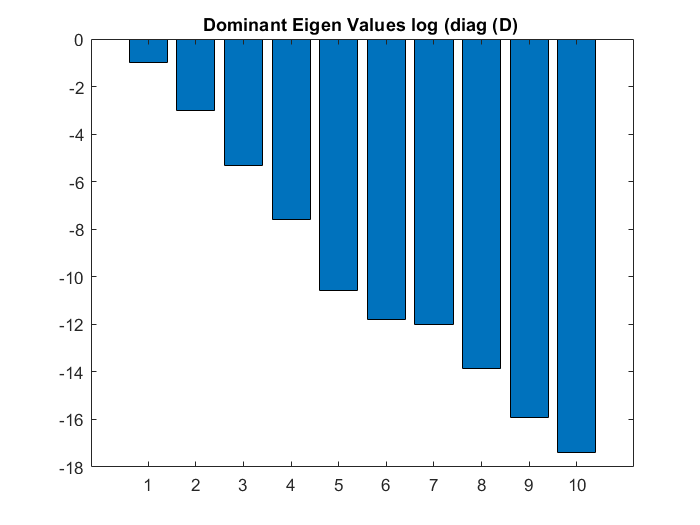


figure (02); 
bar (log (diag (D)))
title ('Dominant Eigen Values log (diag (D) ') 

eigen_idx = 1

eigen_idx = 1

Xhat =  V(:,eigen_idx)'*X;

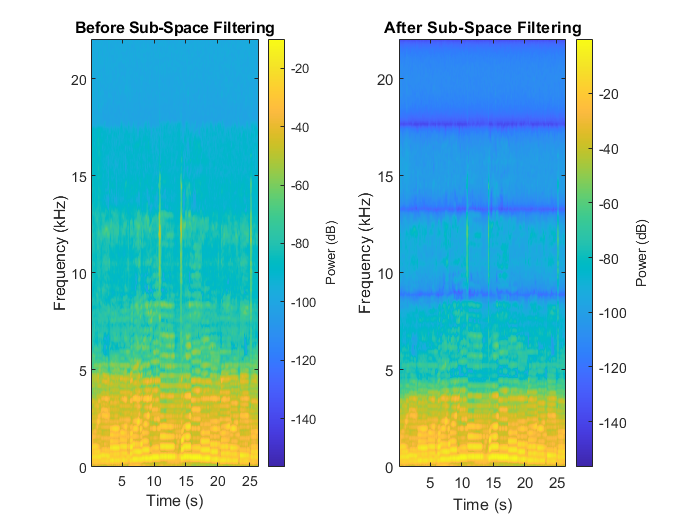

figure (03); 
subplot (1,2,1); pspectrum (data (:,1),Fs, 'spectrogram'); title('Before Sub-Space Filtering')
subplot (1,2,2); pspectrum (Xhat, Fs, 'spectrogram'); title('After Sub-Space Filtering')

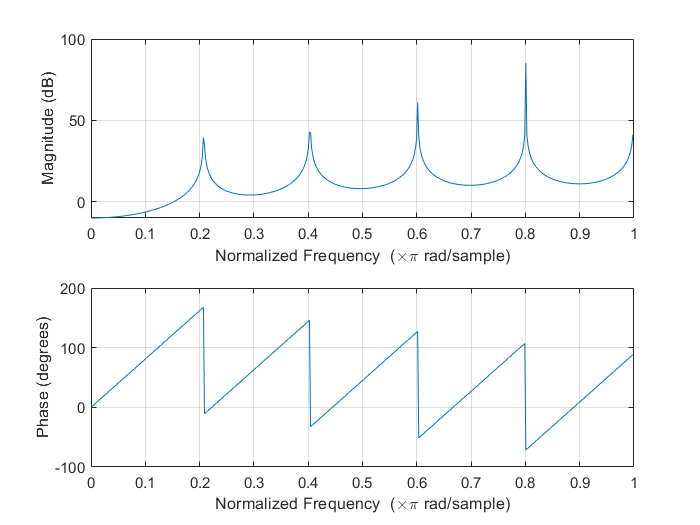

figure (04); 
freqz (1,V(:,eigen_idx))


plot_points = 100000

plot_points = 100000

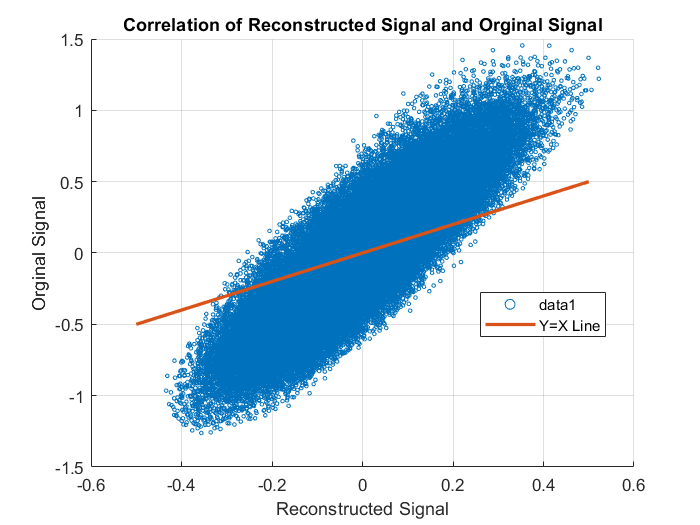

scatter(signal(1:plot_points)',Xhat(1:plot_points),5)
xlabel('Reconstructed Signal')
ylabel('Orginal Signal')
title('Correlation of Reconstructed Signal and Orginal Signal')
hold on
plot([-0.5,0,0.5],[-0.5,0,0.5],'LineWidth',2,'DisplayName','Y=X Line')
legend('Location','best')
grid on


% audio write
filename = "recontructed_eigen-Filters_3.wav";
audiowrite (filename, Xhat, Fs);

filename = "recontructed_eigen-Filter_1.wav";
audiowrite (filename, Xhat, Fs);